# 使用标准的Thin plate spline （TPS）图像非刚性变形算法

下面示例给出了2种方法对畸变的棋盘网格图像做恢复矫正，控制点使用的是棋盘格点坐标。

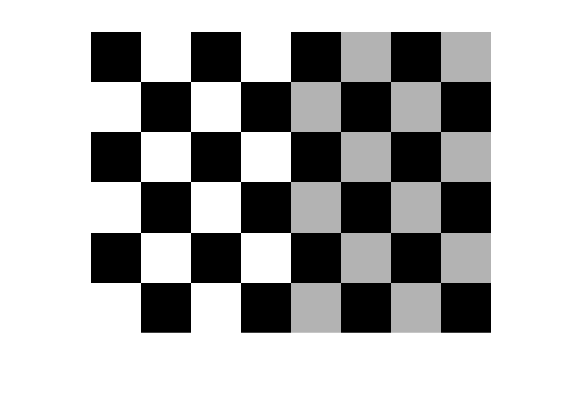

% 畸变一副棋盘网格图像
squareWidth = 50;% in pixels
rows = 3;
cols = 4;
img = checkerboard(squareWidth,rows,cols);
figure(1);imshow(img)

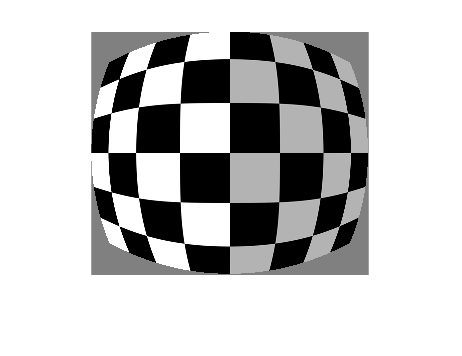


% make a distortion image
height = squareWidth*2*rows;
width = squareWidth*2*cols;
fx = (width+height)/2;
fy = fx;
cx = width/2;
cy = height/2;
k = [fx 0 cx;
    0 fy cy;
    0 0 1];
radialDistortion = [-0.3361,15.8921,28.22]; 
cameraParams = cameraParameters("K",k,"RadialDistortion",radialDistortion);
distortImg = undistortImage(img,cameraParams,"cubic",OutputView="full",FillValues=0.5);
figure(2);imshow(distortImg)

[srcPtX,srcPtY] = ginput(20);

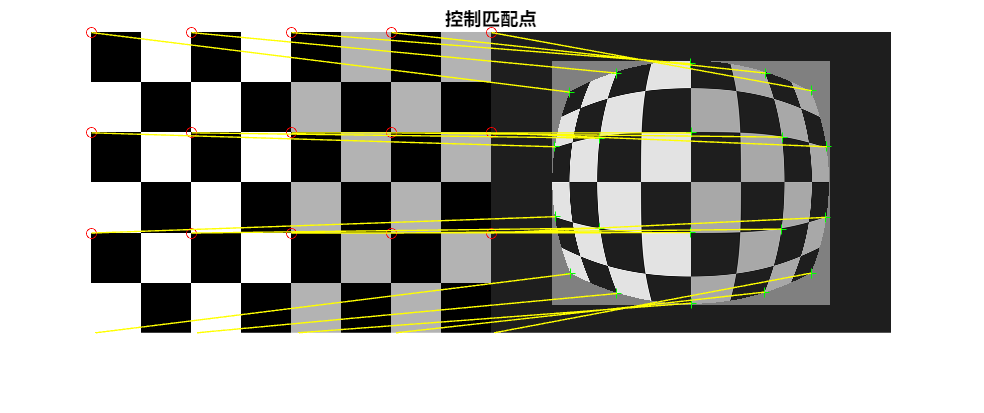

distortPts = [18.173       31.393
       64.771       12.408
       138.98       3.0888
       213.88       12.408
       260.14       30.012
       3.3303        85.93
       47.857         77.3
       139.67       72.123
       231.14       76.265
       275.32        85.93
       3.6754       155.65
       47.857       167.04
       138.98       171.53
       229.76       168.08
       273.94       156.34
       18.863       212.61
       65.461       232.28
       139.67       241.95
       213.19        230.9
       259.79       211.92];

[x,y] = meshgrid(1:2*squareWidth:width+1,1:2*squareWidth:height+1);
x = x'; % 对应上门行优先排列
y = y';
correctPts = [x(:),y(:)];

% figure(2);
% hold on;scatter(distortPts(:,1),distortPts(:,2),100,'red','filled');
% text(distortPts(:,1)+5,distortPts(:,2),string(1:size(distortPts,1)),FontSize=20)
% figure(1);
% hold on;scatter(correctPts(:,1),correctPts(:,2),100,'blue','filled');
% text(correctPts(:,1)+5,correctPts(:,2),string(1:size(correctPts,1)),FontSize=20)

figure;
showMatchedFeatures(img,distortImg,correctPts,distortPts,"montage")
title("控制匹配点")

## 标准的TPS实现

标准的tps算法实现畸变图像矫正：

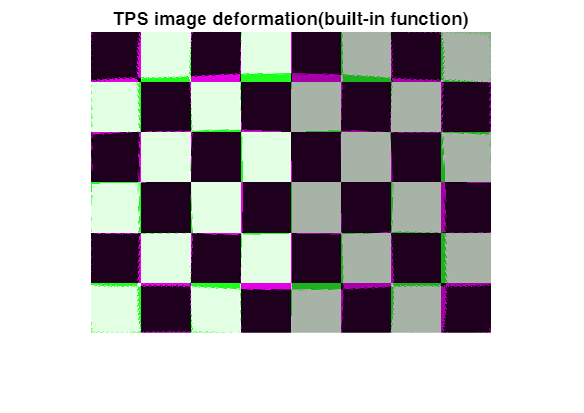

correctedImg1 = warpImageTPS(distortImg, distortPts,correctPts,outputView=imref2d(size(img)));
figure;
imshowpair(img,correctedImg1)
title("TPS image deformation(built-in function)")

## 自定义实现畸变图像矫正

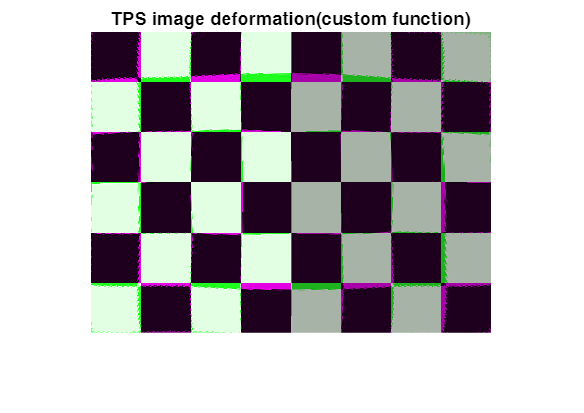

correctedImg2 = warpImageTPS2(distortImg,  distortPts,correctPts,outputView=imref2d(size(img)));
figure;
imshowpair(img,correctedImg2)
title("TPS image deformation(custom function)")